# Assignment 3: Control Techniques Beyond Basic PID

## problem 1:  LeadCompensator for Speed Improvement

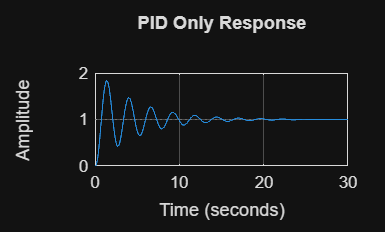

%% Problem 1(a): Baseline PID Controller

s = tf('s');
G = 20/(s*(s+2)*(s+5));

% PID tuning (manual / pidtune)
C_pid = pid(2, 1, 0.1);   % Reasonable starting gains

% Closed-loop system
T_pid = feedback(C_pid*G, 1);

% Step response
figure;
step(T_pid);
grid on;
title('PID Only Response');


% Performance metrics
info_pid = stepinfo(T_pid)

info_pid = struct with fields:
         RiseTime: 0.4665
    TransientTime: 18.5736
     SettlingTime: 18.5736
      SettlingMin: 0.4240
      SettlingMax: 1.8357
        Overshoot: 83.5677
       Undershoot: 0
             Peak: 1.8357
         PeakTime: 1.3926


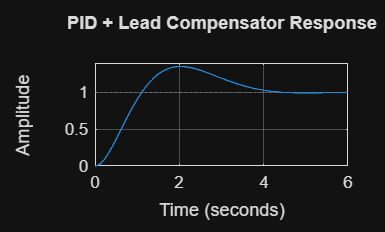



%% Problem 1(b): PID + Lead Compensator

z = 3;
p = 15;
Kc = 2;

C_lead = Kc*(s+z)/(s+p);

% Total controller
C_total = C_pid * C_lead;

% Closed-loop response
T_pid_lead = feedback(C_total*G, 1);

figure;
step(T_pid_lead);
grid on;
title('PID + Lead Compensator Response');


info_pid_lead = stepinfo(T_pid_lead)

info_pid_lead = struct with fields:
         RiseTime: 0.7599
    TransientTime: 4.1209
     SettlingTime: 4.1209
      SettlingMin: 0.9062
      SettlingMax: 1.3519
        Overshoot: 35.1889
       Undershoot: 0
             Peak: 1.3519
         PeakTime: 2.0004


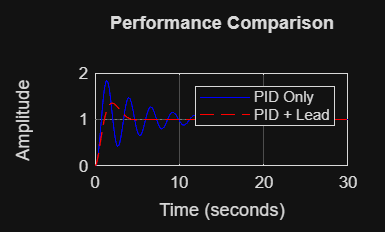



% problem 1(c)
% Comparison Plot

figure;
step(T_pid, 'b', T_pid_lead, 'r--');
grid on;
legend('PID Only', 'PID + Lead');
title('Performance Comparison');

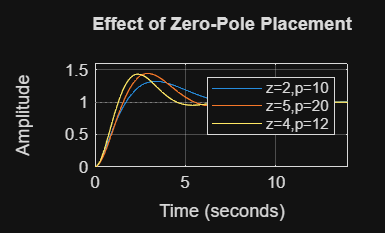


%problem 1(d)
%% Parameter Experimentation

params = [2 10; 5 20; 4 12];
figure; hold on;

for i = 1:size(params,1)
    z = params(i,1);
    p = params(i,2);
    C_lead = (s+z)/(s+p);
    T = feedback(C_pid*C_lead*G, 1);
    step(T);
end

grid on;
legend('z=2,p=10','z=5,p=20','z=4,p=12');
title('Effect of Zero-Pole Placement');

## Problem 2:  LagCompensatorfor Steady-State Accuracy

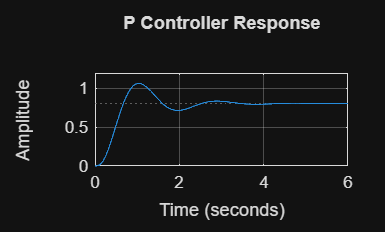

%% Problem 2(a): P Controller

s = tf('s');
G = 50/((s+1)*(s+3)*(s+8));

Kp = 2;
T_p = feedback(Kp*G, 1);

figure;
step(T_p);
grid on;
title('P Controller Response');


% Steady-state error
ess_p = abs(1 - dcgain(T_p))

ess_p = 0.1935

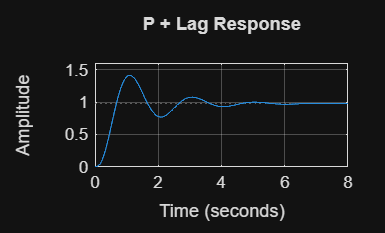



%% Problem 2(b): Lag Compensator

z = 1;
p = 0.1;
Clag = (s+z)/(s+p);

C_total = Kp * Clag;
T_lag = feedback(C_total*G, 1);

figure;
step(T_lag);
grid on;
title('P + Lag Response');


ess_lag = abs(1 - dcgain(T_lag))

ess_lag = 0.0234


%% Problem 2(c): Table - Steady-State Error Comparison

% Settling times
info_p = stepinfo(T_p);
info_lag = stepinfo(T_lag);

% Error reduction percentage
error_reduction = ((ess_p - ess_lag)/ess_p)*100;

% Create table
Problem2_Table = table( ...
    ["P Controller"; "P + Lag Compensator"], ...
    [ess_p; ess_lag], ...
    [info_p.SettlingTime; info_lag.SettlingTime], ...
    [0; error_reduction], ...
    'VariableNames', ...
    {'Controller_Type','Steady_State_Error','Settling_Time','Error_Reduction_Percent'} ...
);

% Display table
Problem2_Table

Problem2_Table = 2×4 table
       Controller_Type       Steady_State_Error    Settling_Time    Error_Reduction_Percent
    _____________________    __________________    _____________    _______________________

    "P Controller"                 0.19355            3.2198                     0         
    "P + Lag Compensator"         0.023438            5.2126                87.891         


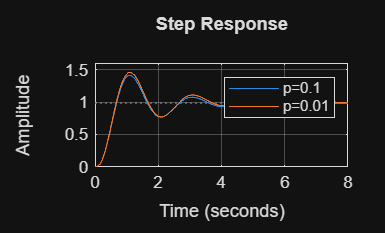


% problem 2(d)
%% Pole Reduction Test

p = 0.01;
Clag2 = (s+1)/(s+p);
T_lag2 = feedback(Kp*Clag2*G, 1);

figure;
step(T_lag, T_lag2);
legend('p=0.1','p=0.01');
grid on;

## Problem 3: Feedforward + Feedback Control

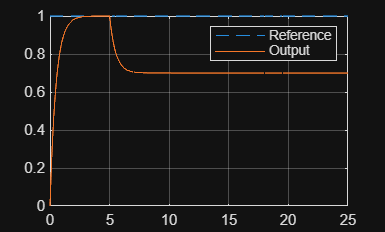

%% Problem 3(a): Feedback Only

s = tf('s');
G = 1/(s+0.5);

Kp = 2; Ki = 1;
Cfb = Kp + Ki/s;

t = 0:0.01:25;
r = ones(size(t));
d = 0.3*(t>=5);

T_fb = feedback(Cfb*G,1);
y = lsim(T_fb, r-d, t);

figure;
plot(t, r, '--', t, y);
legend('Reference','Output');
grid on;

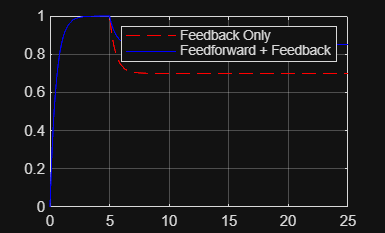



% problem 3(b)
%% Feedforward + Feedback

Kff = 1/dcgain(G);
u_ff = Kff*d;

y_ff = lsim(T_fb, r - d + u_ff, t);

figure;
plot(t, y, 'r--', t, y_ff, 'b');
legend('Feedback Only','Feedforward + Feedback');
grid on;



%% Problem 3(c): Table - Feedback vs Feedforward Performance

% Error signals
error_fb = r - y;
error_ff = r - y_ff;

% Maximum error
max_error_fb = max(abs(error_fb));
max_error_ff = max(abs(error_ff));

% Recovery time (time when error goes below 2%)
idx_fb = find(abs(error_fb) <= 0.02, 1, 'last');
idx_ff = find(abs(error_ff) <= 0.02, 1, 'last');

recovery_fb = t(idx_fb);

Index exceeds the number of array elements. Index must not exceed 2501.

recovery_ff = t(idx_ff);

% Steady-state error

threshold = 0.02;
recovery_fb = NaN;
recovery_ff = NaN;

idx_fb = find(abs(error_fb) <= threshold, 1, 'first');
if ~isempty(idx_fb)
    recovery_fb = t(idx_fb);
end

idx_ff = find(abs(error_ff) <= threshold, 1, 'first');
if ~isempty(idx_ff)
    recovery_ff = t(idx_ff);
end

% Create table
Problem3_Table = table( ...
    ["Feedback Only"; "Feedforward + Feedback"], ...
    [max_error_fb; max_error_ff], ...
    [recovery_fb; recovery_ff], ...
    [ss_error_fb; ss_error_ff], ...
    'VariableNames', ...
    {'Control_Strategy','Max_Error','Recovery_Time','Steady_State_Error'} ...
);

% Display table
Problem3_Table


% problem 3(d)
d2 = 0.2*(t>=15);
y_final = lsim(T_fb, r - d - d2 + u_ff, t);


## Problem 4: Simple MIMO System Control

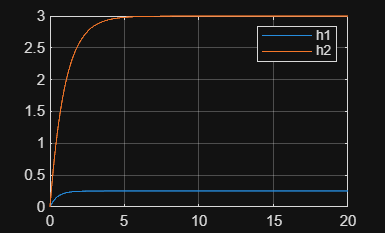

% problem 4(a)
%% MIMO System Definition

G11 = tf(2,[1 1]);
G12 = tf(0.5,[1 2]);
G21 = tf(1,[1 1.5]);
G22 = tf(3,[1 1]);

G = [G11 G12; G21 G22];

t = 0:0.01:20;
u = [ones(size(t)) zeros(size(t))]';
u1 = zeros(length(t),1);
u2 = ones(length(t),1);
u = [u1 u2];
[y,~] = lsim(G, u, t);

figure;
plot(t,y(:,1), t,y(:,2));
legend('h1','h2');
grid on;



%problem 4(b)
Kp1=1.5; Ki1=0.8;
Kp2=1.2; Ki2=0.6;


%% Problem 4(c): Table - Interaction Effects in MIMO System

% Final values
h1_final = h1(end);

The end operator must be used within an array index expression.

h2_final = h2(end);

% Step information (treating each output as SISO for analysis)
info_h1 = stepinfo(h1, t, r1(end));
info_h2 = stepinfo(h2, t, r2(end));

% Settling times
settling_h1 = info_h1.SettlingTime;
settling_h2 = info_h2.SettlingTime;

% Create table
Problem4_Table = table( ...
    ["Tank 1 Level (h1)"; "Tank 2 Level (h2)"], ...
    [h1_final; h2_final], ...
    [settling_h1; settling_h2], ...
    'VariableNames', ...
    {'Output','Final_Value','Settling_Time'} ...
);

% Display table
Problem4_Table



## Answers to summary questions

- When use lead compensator instead of increasing PID gains?: When you want faster response without increasing overshoot caused by high PID gains.

- Advantages of lag compensators: Reduces steady-state error and Improves low-frequency gain. Limitations: Slower transient response.

-  Why is feedforward control called ”proactive” compared to feedback?: It compensates for disturbances before they affect output, unlike feedback which reacts after error occurs.

- Why are MIMO systems harder than SISO?: because it Inputs affect multiple outputs, Interactions cause oscillations and Simple independent controllers are insufficient